# Assignment #1

Connor Cavarretta

ECE 651

09/14/2025

## Question 2.5

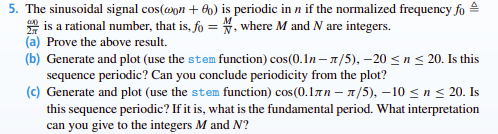

### a) 

A function $x(t)$ is periodic if $x(t) = x(t+T)$ $\forall \ t$

For the signal $cos(\omega_0n+\theta_0)$ to be periodic, the argument of the cosine must be off by $\pm 2\pi$one time period later. Neglecting $\theta_0$, the argument is:

 
$$2\pi\frac{M}{N}n$$


The time period $N_0$ can be defined as the inverse of $f_0$ which here is $\frac{N}{M}$. Replacing $n
$ with $(n+N_0)$, we get:


$$2\pi\frac{M}{N}(n+N_0) = 2\pi\frac{M}{N}\left(n+\frac{N}{M}\right) ... \\

= \ 2\pi\frac{M}{N}n + 2\pi$$


An irrational number does not have this relationship, therefore the normalized frequency must be rational.

### b)

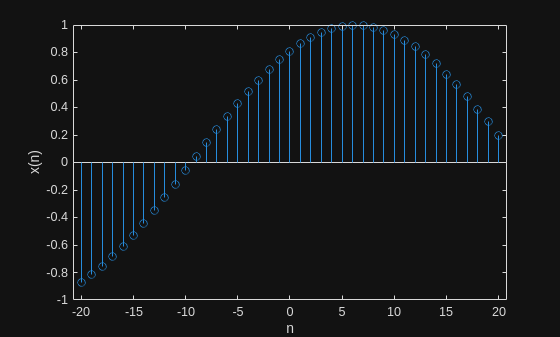

n   = -20:20;
x_n = cos(0.1*n - pi/5);
stem(n, x_n)
xlabel('n');
ylabel('x(n)');

This sequence is **NOT** periodic. We can conclude that this signal is not periodic by considering $\omega_0$:


$$\omega_0 = 0.1 \\
2\pi f_0 = 0.1 \\
f_0 = \frac{0.1}{2\pi}

\text{, Not Rational$$


However, we are not able to conclude from the graph alone due to the chart not capturing the entire period.

### c)

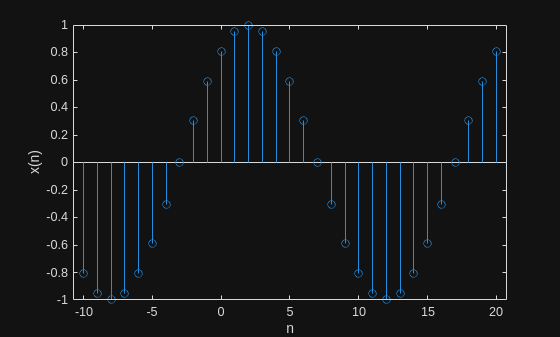

n   = -10:20;
x_n = cos(0.1*pi*n-pi/5);
stem(n, x_n);
xlabel('n')
ylabel('x(n)');

This sequence **IS** periodic and the fundamental period is 20. We can determine this by considering $\omega_0$:


$$\omega_0 = 0.1\pi\\
2\pi f_0 = 0.1\pi \\
f_0 = \frac{0.1}{2}
\rightarrow \frac{1}{20}\text{, Rational} \\
N_0  = \frac{1}{f_0} = 20$$


## Question 2.6

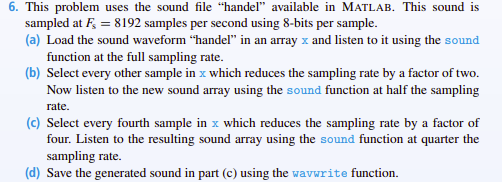

### a)

Load file and play sound.

x = load("handel.mat"); 
%sound(x.y, x.Fs)

### b)

Reduce the sample by a factor of two.

y_halfsample  = x.y(1:2:end);
Fs_halfsample = x.Fs / 2; 
%sound(y_halfsample, Fs_halfsample)

### c)

Reduce the sample by factor of four.

y_quartersample = x.y(1:4:end);
Fs_quartersample = x.Fs / 4; 
%sound(y_quartersample, Fs_quartersample);

### d)

Save the audio file.

% wavwrite has been deprecated, using MATLAB available function instead
%audiowrite("handel_quarter_sample.flac", y_quartersample, Fs_quartersample)

## Question 2.11